The previous model with logistic growth can be adpated to use predator feeding limits, leading to the Holling Type 2 model, given by


$$\frac{dx_1}{dt}=a x_1\left (1-\frac{x_1}{K}\right) - \frac{b x_1x_2 }{1+bhx_1}\\ \frac{dx_2}{dt}=c  \frac{b x_1x_2 }{1+bhx_1} - d x_2 $$


where $a,b,c,d,h,K$ are real constants. The FunctionalResponse script inside the Models folder will return a function handle for the ODE

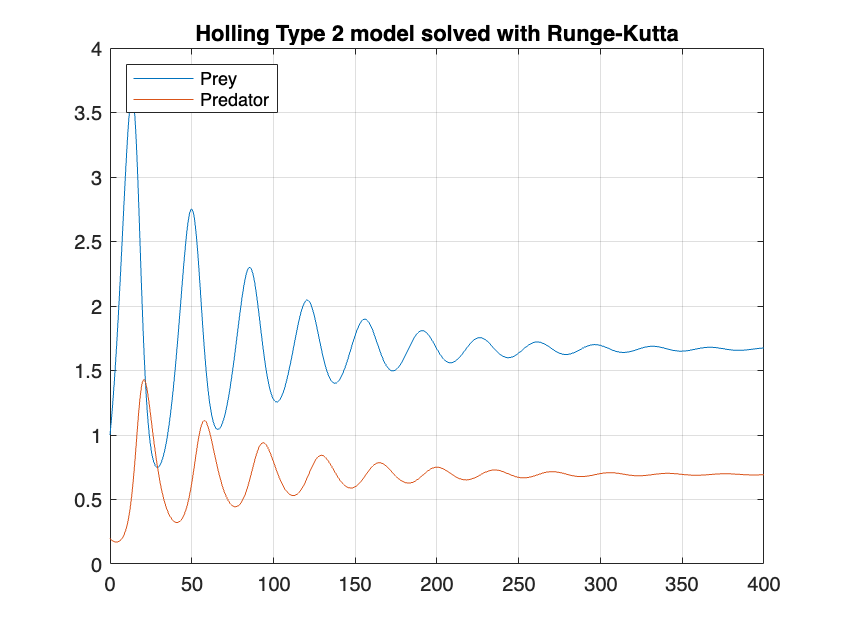

a = 0.2; b = 0.25; c = 0.5; d = 0.2; h = 0.1; K = 10;
prey = 1; predator = 0.2; n = 1000;

f = FunctionalResponse(a,b,c,d,h,K);

[x,t] = RungeKutta(f, 0, 400, [prey; predator], n);
plot(x,t)
grid
legend("Prey","Predator",location="northwest")
title("Holling Type 2 model solved with Runge-Kutta")